## **Računalno upravljanje sustavima**

## **1. Laboratorijska vježba**

## **Modeliranje i simuliranje sustava**

### **1. Uvod**

Brodski inercijalni navigacijski sustav SINS (*Ship's Inertial Navigation System*) zasniva se na načelu mjerenja sila inercije nastale ubrzanjem broda. Ubrzanje (akceleracija) je promjena brzine u jedinici vremena. SINS uređaj pokazuje kurs i brzinu, pri čemu je potrebno poznavati koordinate polazne pozicije broda. Kurs se održava pomoću žirokompasa, akcelerometrom se mjeri prevaljeni put, a računalo automatski ispisuje poziciju broda. Akcelerometri se koriste u svim oblicima navigacije. Za pomorsku navigaciju koriste se dva akcelerometra, jedan za mjerenje pomaka broda u smjeru osi x, a drugi za mjerenje pomaka u smjeru osi y.

Osnovni princip rada akcelerometra su I. i II. Newtonov zakon. Prvi Newtonov zakon ili zakon tromosti kaže da tijelo u mirovanju ostaje u mirovanju, a tijelo koje se giba jednoliko po pravcu zadržava to stanje gibanja sve dok na njega ne počne djelovati rezultantna sila različita od nule. Drugi Newtonov zakon kaže da se smjer kretanja i/ili ubrzanje tijela mijenja u pravcu djelovanja te rezultantne sile. Općenito se izračunom pomaka neke mase može izračunati smjer i brzina kretanja te mase u koordinatnom sustavu. Akcelerometar unutar SINS uređaja služi za mjerenje pomaka broda po x i y osi. Sastoji se od vrlo precizno baždarene mase koja je smještena na stabiliziranu platformu po kojoj je masi omogućeno kretanje bez trenja u smjeru pravca kretanja broda.

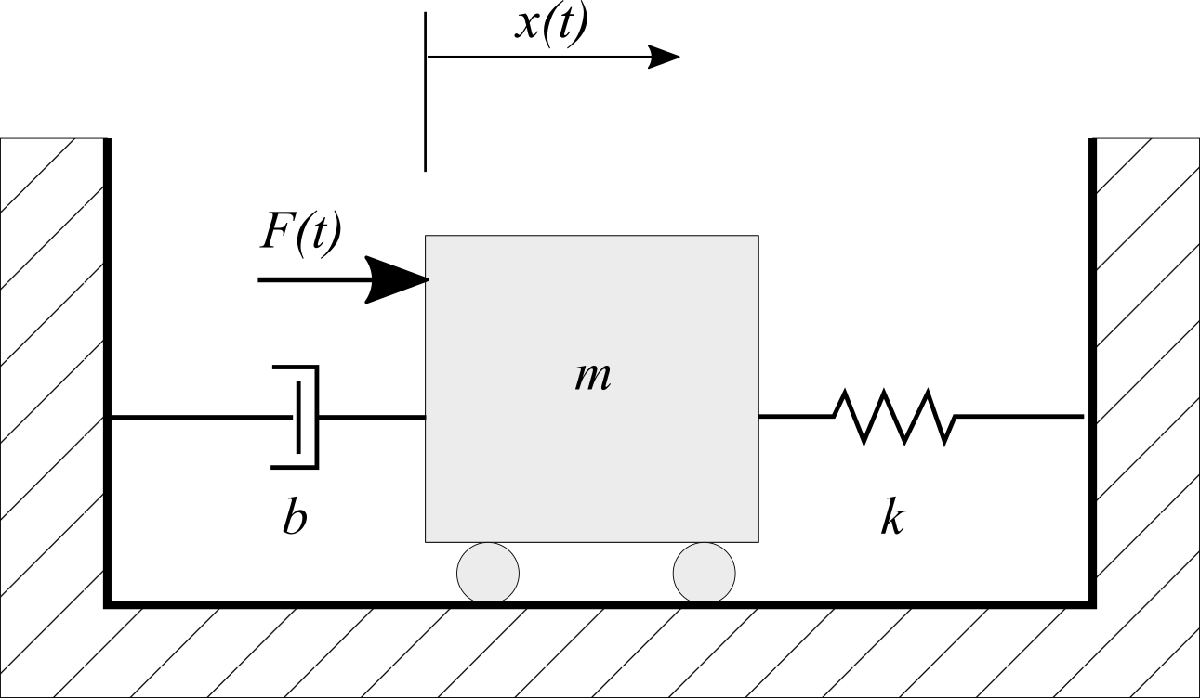

*Slika 1. Shema akcelerometra.*

Masa je učvršćena oprugom na jednom kraju, a prigušnicom na drugom kraju. Na slici 1. prikazan je princip rada akcelerometra za mjerenje pomaka po osi x. Masa unutar akcelerometra pomiče se prilikom promjene brzine broda. Akcelerometar registrira svako (pozitivno i negativno) pomicanje mase. 

Ovakav akcelerometar moguće je opisati diferencijalnom jednadžbom drugog reda:

                                   $m\ddot{x} =F-b\dot{x} -\textrm{kx}$,                                                       (1)

gdje je $m$ masa, $b$ koeficijent prigušenja prigušnice, $k$ koeficijent elastičnosti opruge, $F$ inercijalna sila u smjeru $x$, a $x$ pomak mase od ravnotežnog stanja. Prvom integracijom jednadžbe (1) izračunava se brzina ili promjena brzine u smjeru osi akcelerometra. Drugom integracijom izračunava se promjena položaja broda u koordinatnom sustavu.

%#ok<*NASGU> Ovo spriječava Matlabova upozorenja da se varijabla ne koristi
m = 2.77; % masa [kg]
b = 4.27; % koeficijent prigušenja [kg/s]
k = 4.47; % koeficijent elastičnosti [kg/s^2]

Kako bi se odredio blok dijagram sustava, diferencijalnu jednadžbu sustava (1) potrebno je zapisati u sljedećem obliku:

                                      $\ddot{x} =\frac{F}{m}-\frac{b}{m}\dot{x} -\frac{k}{m}x$.                                                   (2)

Blok dijagram sustava prikazan je slikom 2 i implementiran kao MATLAB/Simulink model *'shema.slx'*.

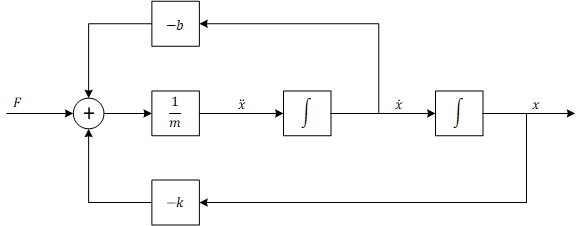

*Slika 2. Blok shema akcelerometra.*

### 2. Prirodni ili slobodni odziv sustava

Prirodni ili slobodni odziv sustava je posljedica isključivo njegovog početnog stanja, dakle, kada na sustav ne djeluje nikakva vanjska pobuda. Početno stanje promatranog sustava određeno je položajem i brzinom u trenutku $t=0$, dakle s $x\left(0\right)$ i $\dot{x} \left(0\right)$.

Zadajmo početno stanje akcelerometra:

x0  = 2.79; % početni položaj u smjeru osi x [m]
dx0 = -0.44; % početna brzina u smjeru osi x [m/s]

Promotrimo ponašanje akcelerometra bez djelovanja vanjske pobude:

F_0 = 0;
t_F = 0;

Pokretanje simulacije modela:

sim_time = 25; % trajanje simulacije [s]
out = sim('shema', sim_time);

Rezultati simulacije pohranjeni su u strukturi `out `u radnom prostoru Matlaba. Ta struktura sadrži polja `tout `(vrijeme), `F `(silu), `x `(pomak), `dx `(brzinu) te `ddx` (akceleraciju). Prikažimo ih grafički:

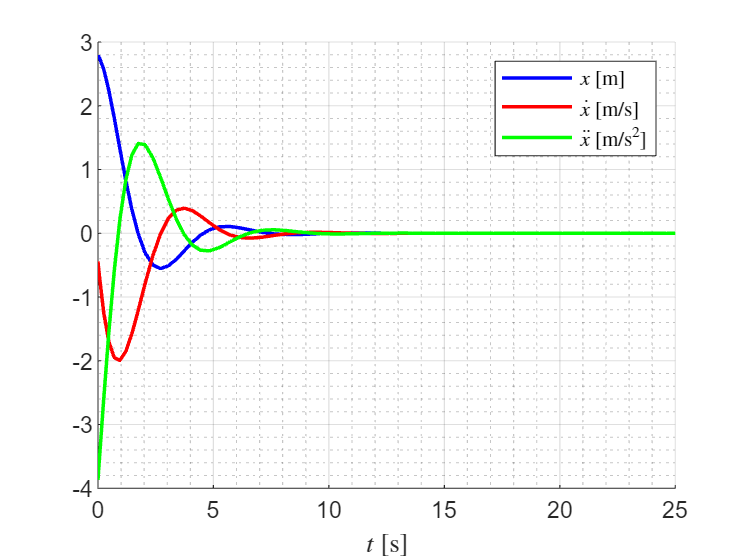

fig1 = figure();
clf;
axes;
hold on;
grid on;
grid minor;
plot(out.tout, out.x, 'b', 'LineWidth', 1.5);
plot(out.tout, out.dx, 'r', 'LineWidth', 1.5);
plot(out.tout, out.ddx, 'g', 'LineWidth', 1.5);
legend({'$x$ [m]', '$\dot{x}$ [m/s]', '$\ddot{x}$ [m/s$^2$]'}, 'Interpreter', 'latex');
xlabel('$t$ [s]', 'Interpreter', 'latex');

Isprobajte kako se odziv sustava mjenja s promjenom početnog stanja, kao i s promjenom parametara akcelerometra ($m$, $b$ i $k$).

### 3. Forsirani ili prinudni odziv sustava

Forsirani ili prinudni odziv sustava je posljedica isključivo pobude sustava, dakle odziv iz ravnotežnog stanja $x\left(t\right)=0$ i $\dot{x} \left(t\right)=0$.

Promotrimo sada kako se sustav ponaša s obzirom na vanjsku silu oblika $F\left(t\right)=F_0 \;S\left(t-t_F \right)$.

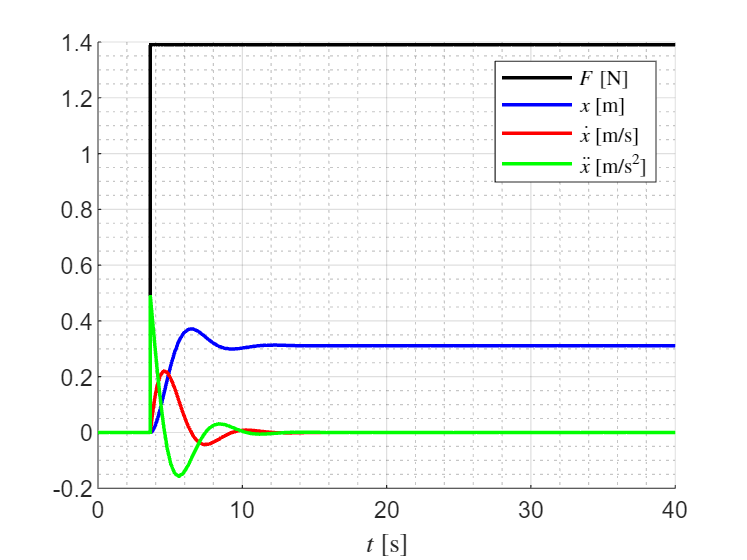

x0 = 0;
dx0 = 0;

% F = F_0 × S(t - T_F)
F_0 = 1.39; % jačina sile [kg m/s^2]
t_F = 3.63; % trenutak djelovanja sile [s]

sim_time = 40;
out = sim('shema', sim_time);

fig2 = figure();
clf;
axes;
hold on;
grid on;
grid minor;
plot(out.tout, out.F, 'k', 'LineWidth', 1.5);
plot(out.tout, out.x, 'b', 'LineWidth', 1.5);
plot(out.tout, out.dx, 'r', 'LineWidth', 1.5);
plot(out.tout, out.ddx, 'g', 'LineWidth', 1.5);
legend({'$F$ [N]', '$x$ [m]', '$\dot{x}$ [m/s]', '$\ddot{x}$ [m/s$^2$]'}, 'Interpreter', 'latex');
xlabel('$t$ [s]', 'Interpreter', 'latex');

Isprobajte kako se odziv sustava mjenja s promjenom jačine i trenutka djelovanja sile, kao i s promjenom parametara akcelerometra ($m$, $b$ i $k$). 

### 4. Ukupni ili totalni odziv sustava

Ukupni ili totalni odziv sustava jednak je zbroju prirodnog i forsiranog odziva sustava.

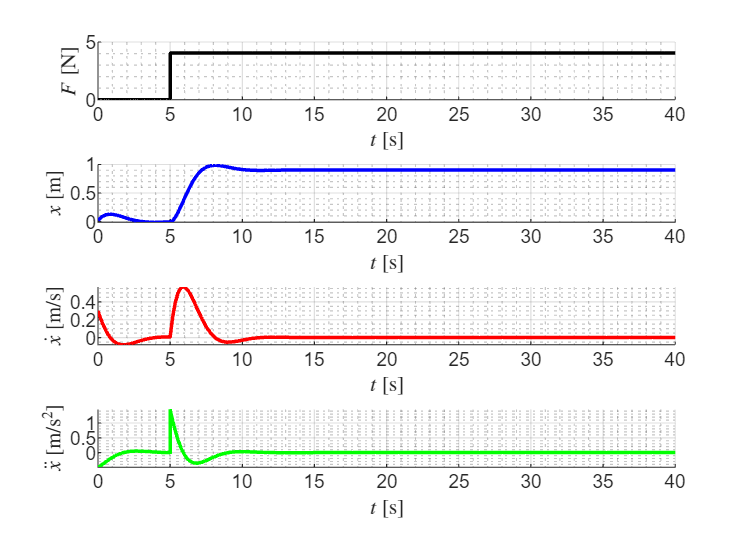

x0 = 0.02;
dx0 = 0.3;

F_0 = 4.04;
t_F = 5;

sim_time = 40;
out = sim('shema', sim_time);

fig3 = figure();
clf;

subplot(4,1,1);
grid on;
grid minor;
hold on;
plot(out.tout, out.F, 'k', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$F$ [N]', 'Interpreter', 'latex');

subplot(4,1,2);
hold on;
grid on;
grid minor;
plot(out.tout, out.x, 'b', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$x$ [m]', 'Interpreter', 'latex');

subplot(4,1,3);
hold on;
grid on;
grid minor;
plot(out.tout, out.dx, 'r', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\dot{x}$ [m/s]', 'Interpreter', 'latex');

subplot(4,1,4);
grid on;
grid minor;
hold on;
plot(out.tout, out.ddx, 'g', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\ddot{x}$ [m/s$^2$]', 'Interpreter', 'latex');

### 5. Prostor stanja

Svaki sustav opisan diferencijalnom jednadžbom $n$-tog reda se može prikazati pomoću sustava $n$ diferencijalnih jednadžbi prvog reda. Pogledajmo još jednom diferencijalnu jednadžbu našeg sustava:

                                                                 $m\ddot{x} +b\dot{x} +\textrm{kx}=F$.                                                           (3)

Uvođenjem varijabli $x_1$ i $x_2$ za koje vrijedi


$$\begin{array}{c}
x_1 =x,\\
x_2 =\dot{x} ,
\end{array}$$


diferencijalna jednadžba (3) može se zapisati pomoću novih varijabli

                                                               $\begin{array}{l}
m{\dot{x} }_2 =-{\textrm{bx}}_2 -{\textrm{kx}}_1 +F,\\
\;\;\;\;{\dot{x} }_1 =x_2 \ldotp 
\end{array}$                                                       (4)

Ako je sila $F$ ulaz u sustav, a izlaz iz sustava je mjereni položaj $x$, model sustava je moguće zapisati u matričnom obliku


$$\begin{array}{l}
\dot{\mathbf{x}} =\mathbf{A}\;\mathbf{x}+\mathbf{B}\;\mathbf{u},\\
\mathbf{y}=\mathbf{C}\;\mathbf{x}+\mathbf{D}\;\mathbf{u},
\end{array}$$


pri čemu je $\mathbf{x}={\left\lbrack \begin{array}{cc}
x_1  & x_2 
\end{array}\right\rbrack }^T$ vektor stanja sustava, $\mathbf{u}=\left\lbrack \begin{array}{c}
F
\end{array}\right\rbrack$ vektor ulaznih signala, $\mathbf{y}=\left\lbrack \begin{array}{c}
y_1 
\end{array}\right\rbrack$vektor mjerenih varijabli sustava, a $\mathbf{A}$, $\mathbf{B}$, $\mathbf{C}$ i$\;\mathbf{D}$ su matrice sustava. Odredite elemente tih matrica tako da opisuju zadani sustav i nadopunite ih u nastavku:


$$\mathbf{A}=\left\lbrack \begin{array}{cc}
 & \\
 & 
\end{array}\right\rbrack$$
                        
$$\mathbf{B}=\left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack$$
                        
$$\mathbf{C}=\left\lbrack \begin{array}{cc}
 & 
\end{array}\right\rbrack$$
                        
$$\mathbf{D}=\left\lbrack \begin{array}{c}

\end{array}\right\rbrack$$


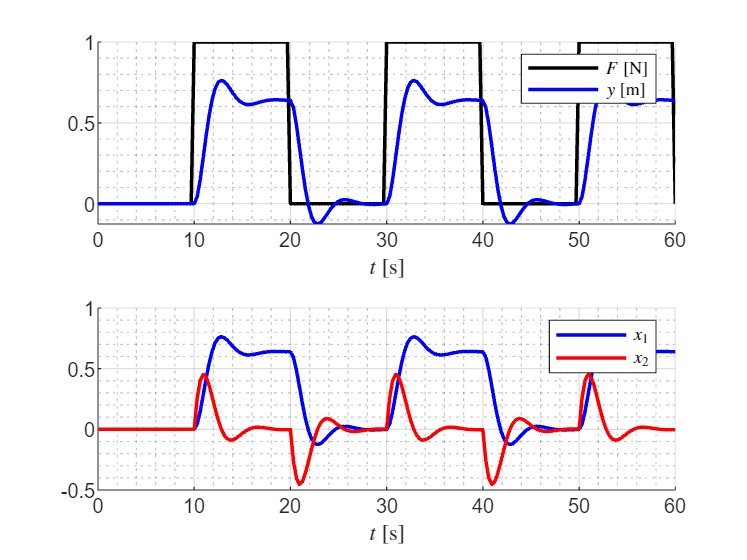

m = 2.85; % [kg]
b = 3.28; % [kg/s]
k = 4.47; % [kg/s^2]

% popunite sljedeća polja s odgovarajućim izrazima
A = [0, 1; ...
     -k/m, -b/m];

B = [0; ...
     1];

C = [1, 0];

D = 0;

% kreirajmo model u prostoru stanja
sys = ss(A,B,C,D);

% ulazni signal
[u, t] = gensig('square', 20, 60);

% simulacija sustava
[y, tout, x] = lsim(sys, u, t);

fig4 = figure();
clf;

subplot(2,1,1);
hold on;
grid on;
grid minor;
plot(tout, u, 'k', 'LineWidth', 1.5);
plot(tout, y, 'b', 'LineWidth', 1.5);
legend({'$F$ [N]', '$y$ [m]'}, 'Interpreter', 'latex');
xlabel('$t$ [s]', 'Interpreter', 'latex');

subplot(2,1,2);
hold on;
grid on;
grid minor;
plot(tout, x(:,1), 'b', 'LineWidth', 1.5);
plot(tout, x(:,2), 'r', 'LineWidth', 1.5);
legend({'$x_1$', '$x_2$'}, 'Interpreter','latex');
xlabel('$t$ [s]', 'Interpreter','latex');

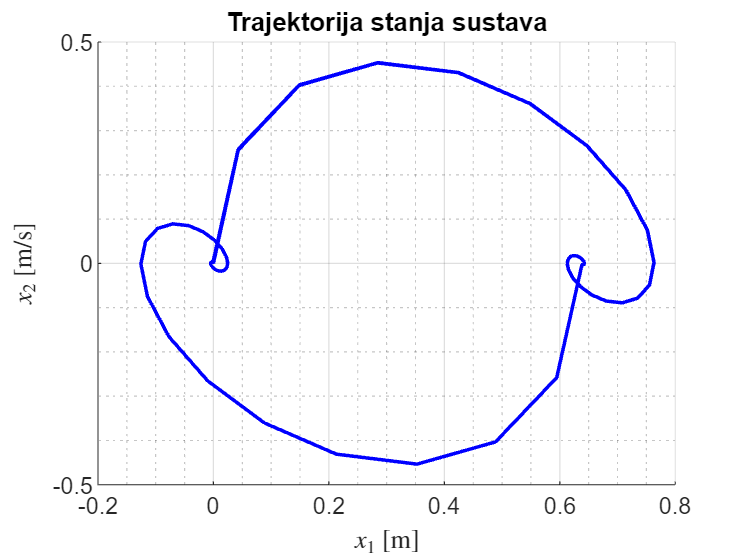

fig5 = figure();
clf;
axes;
hold on;
grid on;
grid minor;
plot(x(:,1), x(:,2), 'b', 'LineWidth', 1.5);
xlabel('$x_1$ [m]', 'Interpreter', 'latex');
ylabel('$x_2$ [m/s]', 'Interpreter', 'latex');
title('Trajektorija stanja sustava');

### 6. Pitanja

- Kako se mijenja odziv sustava prilikom smanjenja i povećanja konstante elastičnosti, faktora prigušenja i mase sustava? ***Odziv sustava se pri smanjenju konstante elastičnosti ponaša "krutije", odnosno smanjuje frekvenciju oscilacija. Povećanjem dobivamo suprotni učinak. Smanjivanjem faktora prigušenja produljujemo vrijeme potrebno da se sustav vrati u ravnotežno stanje, a povećanjem faktora prigušenja smanjujemo vrijeme potrebno za postizanje ravnotežnog stanja. Povećanjem mase trebamo utrošiti više sile i vremena za postizanje ravnotežnog stanja.***

- Što se događa sa odzivom sustava ako se faktor prigušenja postavi na nulu? ***Sustav je neprigušen, odnosno oscilira beskonačno dugo u vremenu t.***

- Što se događa sa odzivom sustava ako se konstanta elastičnosti postavi na nulu? ***Postavljanjem konstante elastičnosti na nulu dobivamo "glatki" prijelaz u ravnotežno stanje, odnosno sustav ne oscilira oko ravnotežnog stanja prije smirivanja.***

- Kako na odziv sustava utječe promjena početnog položaja (mjenjajte početni položaj mase u pozitivnom i negativnom smjeru)? ***Utječe na smjer djelovanja pomaka, brzine i akceleracije.***

- Koja je razlika između prirodnog i prinudnog odziva? ***Prirodni odziv je odziv uslijed početnih stanja, a prinudni odziv je odziv uslijed pobude na ulazu sustava dok su sva početna stanja postavljena na nulu.***

- Kako sustav reagira na djelovanje vanjske sile? ***Pomiče se u smjeru djelovanja sile do određene točke (određene faktorom prigušenja, konstante elastičnosti i mase sustava). Nakon prestanka djelovanja sile, vraća se u ravnotežni položaj.***